%%%%%      迁移学习
%%%%%%     采样频率1000MHz
%%%%%%%     载频  [Fs/10, Fs/4]= [100MHz 250MHz]
%%%%%%%%    带宽  [Fs/40, Fs/16]=[25MHz  62.5MHz]
%%%%%%%%    采样点数  [512, 1920]
%%%%%%%%%%%%   产生新的数据集，每个信噪比点产生200张，一种信号产生200*11张，总添加200*11*7张


addpath('yuan\');
rng default         %用默认种子，matlab刚开始默认就是0
x=2*11;  %信号个数
[wav, mod] = gaiGenerateRadarWaveforms(x);


parentDir = '124';%获取操作系统的文件路径，将其赋值给 parentDir 变量
dataDir = 'WVD';%定义了一个名为 dataDir 的变量，用于存放生成的数据文件。这里将其设置为 TFDDatabase
% 有STFT,CWT,WVD
helperGenerateTFDfiles(parentDir,dataDir,wav,mod,2000e6)
                                                % parentDir：时频分析图数据文件的保存路径。
                                                % dataDir：生成的数据文件所在的目录名称。
                                                % wav：生成时频分析图的波形。
                                                % mod：波形的调制类型。
                                                % 2000e6：信号的采样率。


folders = fullfile(parentDir,dataDir,{'RECT','LFM','NLFM','BPSK','QPSK','BFSK','QFSK'});
%创建一个包含三个字符串的元胞数组，每个字符串都是一个文件夹名，代表了数据集中的三个不同类别。

imds = imageDatastore(folders,...
    'FileExtensions','.png','LabelSource','foldernames','ReadFcn',@readTFDForSqueezeNet);
% 创建了一个 imageDatastore 对象，其中 folders 参数指定了待加载图像所在的文件夹路径
%'FileExtensions','.png' 表示只加载 PNG 格式的图像文件
%LabelSource','foldernames' 参数指定了标签来源，表示使用文件夹的名称作为图像的标签
%ReadFcn',@readTFDForSqueezeNet 参数指定了一个函数句柄，该函数用于读取和预处理图像数据。


%%%%%%%%加载模型
load('net\shendunet.mat');


[imdsTrain,imdsTest,imdsValidation] = splitEachLabel(imds,0.8,0.1);
%每个标签的训练数据占 80%，测试数据占 10%，验证数据占 10%。

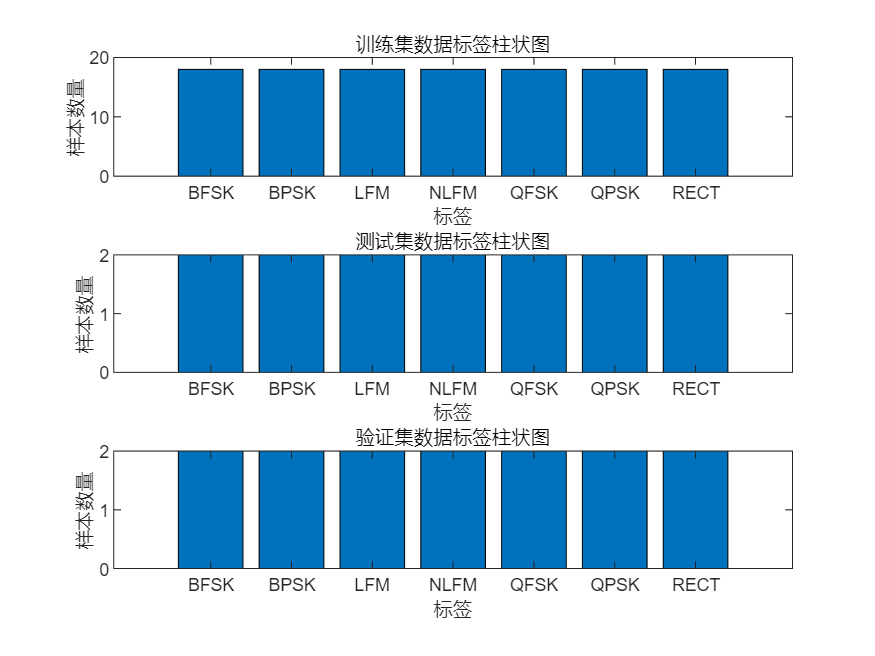

%%%%%%%%%%%%%%%    数据集分布图   %%%%%%%%%%%%%%%%%%%

% 统计每个标签在训练集中的样本数量
trainLabelCount = countEachLabel(imdsTrain);
% 统计每个标签在测试集中的样本数量
testLabelCount = countEachLabel(imdsTest);
% 统计每个标签在验证集中的样本数量
validationLabelCount = countEachLabel(imdsValidation);
% 提取标签和对应的样本数量
labels = trainLabelCount.Label;
trainCounts = trainLabelCount.Count;
testCounts = testLabelCount.Count;
validationCounts = validationLabelCount.Count;
% 绘制训练集柱状图
subplot(3, 1, 1);
bar(trainCounts)
xlabel('标签')
ylabel('样本数量')
title('训练集数据标签柱状图')
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels)
% 绘制测试集柱状图
subplot(3, 1, 2);
bar(testCounts)
xlabel('标签')
ylabel('样本数量')
title('测试集数据标签柱状图')
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels)
% 绘制验证集柱状图
subplot(3, 1, 3);
bar(validationCounts)
xlabel('标签')
ylabel('样本数量')
title('验证集数据标签柱状图')
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels)


%%%%%%%%%%%%%%%%深度学习模型%%%%%%%%%%%%%%
lgraphSqz = layerGraph(trainedNet);

%%%%%%%%%%%%%%%训练参数设置
options = trainingOptions('sgdm', ...
    'MiniBatchSize',154, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','auto',...
    'ValidationData',imdsValidation);

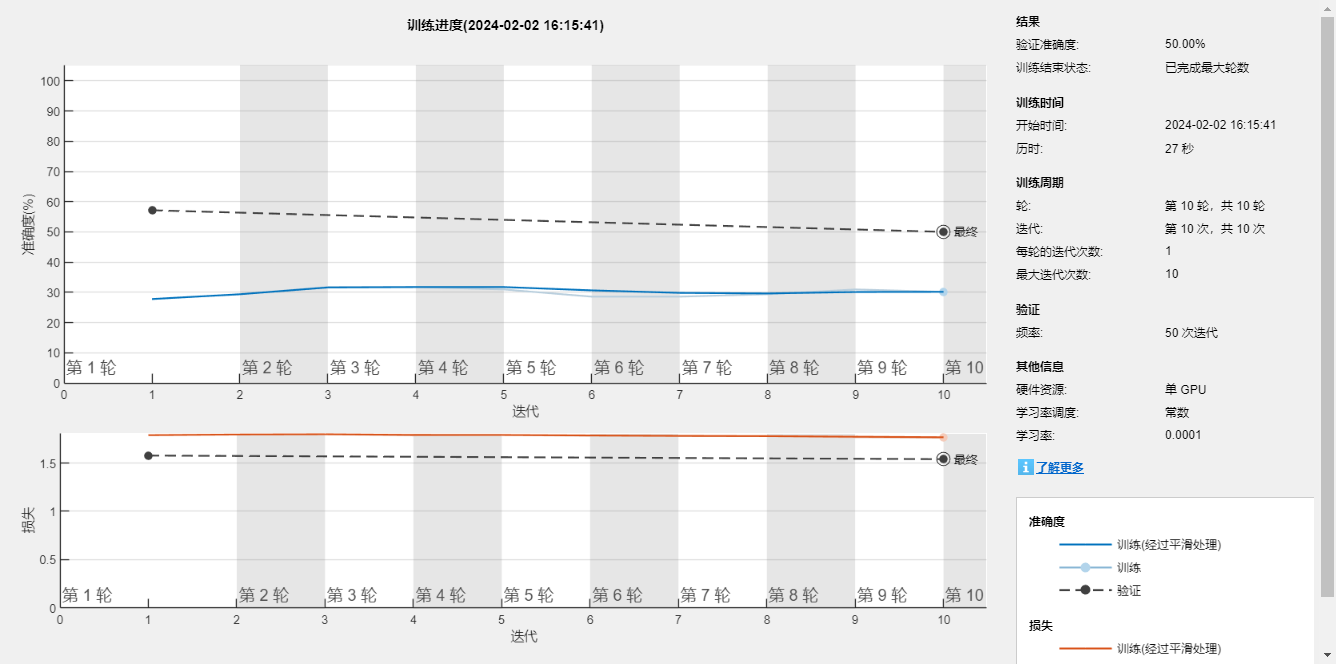

%%%%%%%%%%%%%%%%%%%%模型训练%%%%%%%%%%%%
trainedNet = trainNetwork(imdsTrain,lgraphSqz,options);

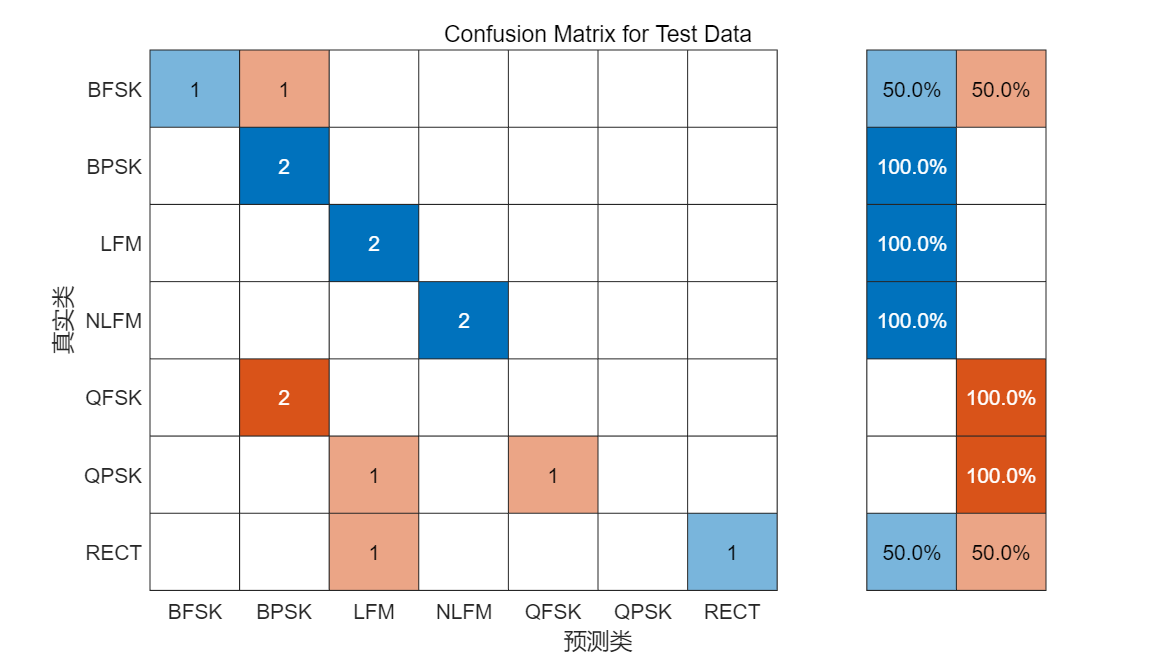

%%%%%%%%%%%%%%%%%%%输出混淆图并保存网络%%%%%%%%%%%%%%%
predicted = classify(trainedNet,imdsTest);
% figure;
% confusionchart(predicted,imdsTest.Labels,'Normalization','column-normalized')


figure
cm = confusionchart(imdsTest.Labels,predicted);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 740 424];


%保存网络
save('net\qianyinet','trainedNet');